Colmap - Colmap

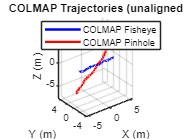

[frame_id_1, COLMAP_1] = ...
    load_colmap_trajectory('COLMAP fisheye/text/frames.txt');

[frame_id_2, COLMAP_2] = ...
    load_colmap_trajectory('COLMAP pinhole/text/frames.txt');

figure;
hold on;

plot3(COLMAP_1(:,1), COLMAP_1(:,2), COLMAP_1(:,3), ...
      'b-', 'LineWidth', 2);

plot3(COLMAP_2(:,1), COLMAP_2(:,2), COLMAP_2(:,3), ...
      'r-', 'LineWidth', 2);

legend('COLMAP Fisheye', 'COLMAP Pinhole');

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('COLMAP Trajectories (unaligned)');

grid on;
axis equal;
view(3);
rotate3d on;

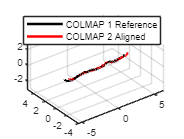

[d, COLMAP_2_aligned, transform_2_to_1] = procrustes(COLMAP_1, COLMAP_2);


figure;
hold on;

plot3(COLMAP_1(:,1), COLMAP_1(:,2), COLMAP_1(:,3), 'k-', 'LineWidth', 2);
plot3(COLMAP_2_aligned(:,1), COLMAP_2_aligned(:,2), COLMAP_2_aligned(:,3), ...
      'r-', 'LineWidth', 2);

legend('COLMAP 1 Reference', 'COLMAP 2 Aligned');

grid on;
axis equal;
view(3);
rotate3d on;



err = vecnorm(COLMAP_1 - COLMAP_2_aligned, 2, 2);

rmse = sqrt(mean(err.^2));
mean_err = mean(err);
max_err = max(err);

fprintf('RMSE: %.4f m\n', rmse);

RMSE: 0.3671 m


fprintf('Mean error: %.4f m\n', mean_err);

Mean error: 0.3152 m


fprintf('Max error: %.4f m\n', max_err);

Max error: 0.7957 m


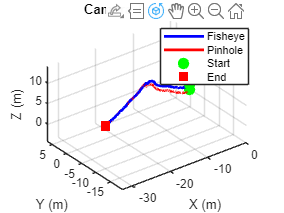

traj_fisheye = load('MonoSLAM fisheye/final/trajectory.mat').trajectory;
traj_pinhole = load('MonoSLAM pinhole/final/trajectory.mat').trajectory;

% Find first [0;0;0] column
idx1 = find(all(traj_fisheye == 0, 1), 1);
idx2 = find(all(traj_pinhole == 0, 1), 1);

% If no zero column exists, use full length
if isempty(idx1)
    n1 = size(traj_fisheye, 2);
else
    n1 = idx1 - 1;
end

if isempty(idx2)
    n2 = size(traj_pinhole, 2);
else
    n2 = idx2 - 1;
end

% Plot
figure;
hold on;

% Trajectories
h1 = plot3(traj_fisheye(1,1:n1), ...
           traj_fisheye(2,1:n1), ...
           traj_fisheye(3,1:n1), ...
           'b-', 'LineWidth', 2);

h2 = plot3(traj_pinhole(1,1:n2), ...
           traj_pinhole(2,1:n2), ...
           traj_pinhole(3,1:n2), ...
           'r-', 'LineWidth', 2);

% Shared start markers
h3 = plot3(traj_fisheye(1,1), traj_fisheye(2,1), traj_fisheye(3,1), ...
      'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

plot3(traj_pinhole(1,1), traj_pinhole(2,1), traj_pinhole(3,1), ...
      'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% Shared end markers
h4 = plot3(traj_fisheye(1,n1), traj_fisheye(2,n1), traj_fisheye(3,n1), ...
      'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

plot3(traj_pinhole(1,n2), traj_pinhole(2,n2), traj_pinhole(3,n2), ...
      'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Camera Trajectories');

legend([h1, h2, h3, h4], ...
       'Fisheye', 'Pinhole', 'Start', 'End');

grid on;
axis equal;
view(3);
rotate3d on;

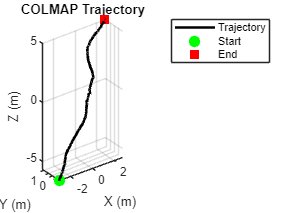

filename = 'COLMAP fisheye/bestmodel/frames.txt';

fid = fopen(filename, 'r');

data = textscan(fid, ...
    '%f %f %f %f %f %f %f %f %f %*[^\n]', ...
    'CommentStyle', '#');

fclose(fid);

frame_id = data{1};

QW = data{3};
QX = data{4};
QY = data{5};
QZ = data{6};

TX = data{7};
TY = data{8};
TZ = data{9};

COLMAP = zeros(length(frame_id), 3);

for i = 1:length(frame_id)
    q = [QW(i), QX(i), QY(i), QZ(i)];
    t = [TX(i); TY(i); TZ(i)];

    R = quat2rotm(q);

    % Camera/rig center in world coordinates
    C = -R' * t;

    COLMAP(i,:) = C';
end

figure;

plot3(COLMAP(:,1), ...
      COLMAP(:,2), ...
      COLMAP(:,3), ...
      'k-', 'LineWidth', 2);

hold on;

% Start point
plot3(COLMAP(1,1), ...
      COLMAP(1,2), ...
      COLMAP(1,3), ...
      'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% End point
plot3(COLMAP(end,1), ...
      COLMAP(end,2), ...
      COLMAP(end,3), ...
      'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('COLMAP Trajectory');

legend('Trajectory', 'Start', 'End');

grid on;
axis equal;
view(3);
rotate3d on;

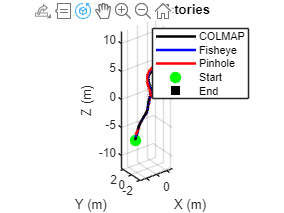

% Convert COLMAP frame IDs to trajectory indices
traj_idx = frame_id * 30;


% Use same COLMAP entries
colmap_matched = COLMAP(1:end-1, :);


% Extract corresponding MonoSLAM trajectory points
traj_fisheye_matched = traj_fisheye(:, traj_idx(1:end-1))';
traj_pinhole_matched = traj_pinhole(:, traj_idx(1:end-1))';

% Procrustes: align MonoSLAM trajectories to COLMAP
[d_fisheye, traj_fisheye_aligned, transform_fisheye] = ...
    procrustes(COLMAP(1:end-1,:), traj_fisheye_matched(:,1:3));

[d_pinhole, traj_pinhole_aligned, transform_pinhole] = ...
    procrustes(COLMAP(1:end-1,:), traj_pinhole_matched(:,1:3));



figure;
hold on;

% COLMAP reference
h1 = plot3(colmap_matched(:,1), ...
           colmap_matched(:,2), ...
           colmap_matched(:,3), ...
           'k-', 'LineWidth', 2);

% Fisheye aligned
h2 = plot3(traj_fisheye_aligned(:,1), ...
           traj_fisheye_aligned(:,2), ...
           traj_fisheye_aligned(:,3), ...
           'b-', 'LineWidth', 2);

% Pinhole aligned
h3 = plot3(traj_pinhole_aligned(:,1), ...
           traj_pinhole_aligned(:,2), ...
           traj_pinhole_aligned(:,3), ...
           'r-', 'LineWidth', 2);

% Shared start marker
h4 = plot3(colmap_matched(1,1), ...
           colmap_matched(1,2), ...
           colmap_matched(1,3), ...
           'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% Shared end marker
h5 = plot3(colmap_matched(end,1), ...
           colmap_matched(end,2), ...
           colmap_matched(end,3), ...
           'ks', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Aligned Trajectories');

legend([h1,h2,h3,h4,h5], ...
       'COLMAP', 'Fisheye', 'Pinhole', 'Start', 'End');

grid on;
axis equal;
view(3);
rotate3d on;

% Errors per matched frame
err_fisheye = vecnorm(colmap_matched - traj_fisheye_aligned, 2, 2);
err_pinhole = vecnorm(colmap_matched - traj_pinhole_aligned, 2, 2);

% Summary metrics
rmse_fisheye = sqrt(mean(err_fisheye.^2));
rmse_pinhole = sqrt(mean(err_pinhole.^2));

mean_fisheye = mean(err_fisheye);
mean_pinhole = mean(err_pinhole);

median_fisheye = median(err_fisheye);
median_pinhole = median(err_pinhole);

max_fisheye = max(err_fisheye);
max_pinhole = max(err_pinhole);

fprintf('Fisheye RMSE: %.4f m\n', rmse_fisheye);

Fisheye RMSE: 0.3507 m


fprintf('Pinhole RMSE: %.4f m\n', rmse_pinhole);

Pinhole RMSE: 0.5759 m



fprintf('Fisheye mean error: %.4f m\n', mean_fisheye);

Fisheye mean error: 0.3255 m


fprintf('Pinhole mean error: %.4f m\n', mean_pinhole);

Pinhole mean error: 0.5297 m



fprintf('Fisheye median error: %.4f m\n', median_fisheye);

Fisheye median error: 0.3264 m


fprintf('Pinhole median error: %.4f m\n', median_pinhole);

Pinhole median error: 0.5126 m



fprintf('Fisheye max error: %.4f m\n', max_fisheye);

Fisheye max error: 0.6163 m


fprintf('Pinhole max error: %.4f m\n', max_pinhole);

Pinhole max error: 1.0672 m


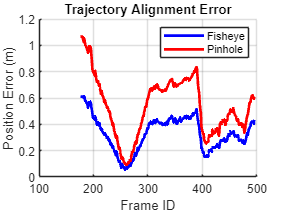


figure;
hold on;

plot(frame_id(1:end-1), err_fisheye, 'b-', 'LineWidth', 2);
plot(frame_id(1:end-1), err_pinhole, 'r-', 'LineWidth', 2);

xlabel('Frame ID');
ylabel('Position Error (m)');
title('Trajectory Alignment Error');

legend('Fisheye', 'Pinhole');
grid on;

function [frame_id, COLMAP] = load_colmap_trajectory(filename)

    fid = fopen(filename, 'r');

    data = textscan(fid, ...
        '%f %f %f %f %f %f %f %f %f %*[^\n]', ...
        'CommentStyle', '#');

    fclose(fid);

    frame_id = data{1};

    QW = data{3};
    QX = data{4};
    QY = data{5};
    QZ = data{6};

    TX = data{7};
    TY = data{8};
    TZ = data{9};

    COLMAP = zeros(length(frame_id), 3);

    for i = 1:length(frame_id)

        q = [QW(i), QX(i), QY(i), QZ(i)];
        t = [TX(i); TY(i); TZ(i)];

        R = quat2rotm(q);

        % Camera center in world coordinates
        C = -R' * t;

        COLMAP(i,:) = C';

    end
end